%% =============================================================
%   CONTROL PI + D - SISTEMA DIRECCIONAL (YAW - ψ)
%   -------------------------------------------------------------
s = tf('s');

%% === CARGA DEL MODELO LATERAL ===
G = tf(latmod);

%% === 1. CANAL YAW (ψ) ==========================================
disp('=== CANAL YAW (ψ) ===');

=== CANAL YAW (ψ) ===


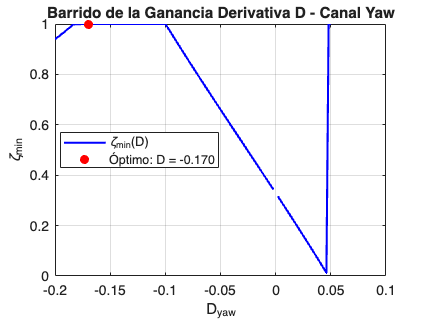


% --- Extraer canal YAW ---
G_psi = G('psi','rudder');   % salida: ángulo direccional
G_r   = G('r','rudder');     % salida: velocidad angular direccional
G_psi = G_psi(1,1);
G_r   = G_r(1,1);

%% --- 2. Barrido de la ganancia derivativa D (lazo interno SAS) ---
D_values = -0.2:0.002:0.05;
zeta_min = nan(size(D_values));

for i = 1:length(D_values)
    D = D_values(i);
    G_sas = feedback(D * G_r, 1);
    [~, zeta, p] = damp(G_sas);

    % Filtrar polos válidos y estables
    if isempty(zeta) || any(isnan(zeta))
        zeta_min(i) = NaN;
    else
        zeta_estables = zeta(real(p) < 0);
        if isempty(zeta_estables)
            zeta_min(i) = NaN;
        else
            zeta_min(i) = min(zeta_estables);
        end
    end
end

% --- Buscar valor óptimo ---
[~, idx_opt] = max(zeta_min);
D_opt = D_values(idx_opt);
zeta_opt = zeta_min(idx_opt);

figure('Color', 'w');
plot(D_values, zeta_min, 'b', 'LineWidth', 1.5); hold on;
plot(D_opt, zeta_opt, 'ro', 'MarkerFaceColor', 'r');
xlabel('D_{yaw}');
ylabel('\zeta_{min}');
title('Barrido de la Ganancia Derivativa D - Canal Yaw');
legend('\zeta_{min}(D)', sprintf('Óptimo: D = %.3f', D_opt), 'Location', 'best');
grid on;


fprintf('Ganancia derivativa óptima (Yaw): D = %.4f, ζ = %.3f\n', D_opt, zeta_opt);

Ganancia derivativa óptima (Yaw): D = -0.1700, ζ = 1.000


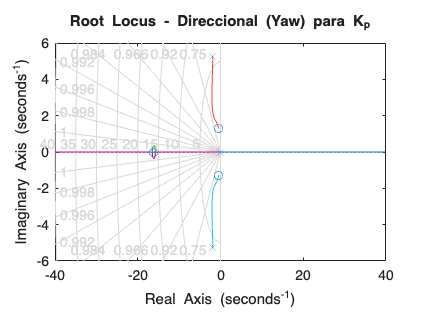


% --- Cierre del lazo interno (SAS) ---
G_sas_yaw = feedback(D_opt * G_r, 1);

%% --- 3. Diseño del Controlador PI (lazo externo CAS) ---
% Analizar la planta yaw con root locus
figure('Color', 'w');
rlocus(G_psi);
title('Root Locus - Direccional (Yaw) para K_p');
grid on;

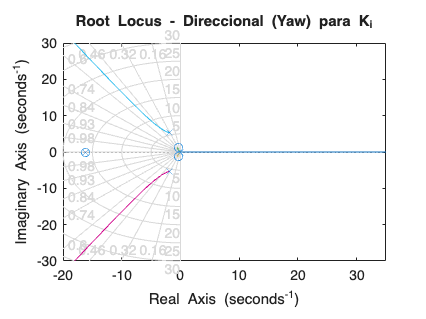


% --- Elección de Kp ---
% Queremos que los polos dominantes queden con ζ ≈ 0.7 (respuesta estable)
Kp_yaw = -0.8;   % valor elegido observando desplazamiento hacia estabilidad

figure('Color', 'w');
rlocus((1/s) * G_psi);
title('Root Locus - Direccional (Yaw) para K_i');
grid on;


% --- Elección de Ki ---
% El integrador se ajusta para eliminar error estacionario sin sobrepasar ζ
Ki_yaw = -0.1;   % ajustado para respuesta rápida sin sobrepico alto

fprintf('Ganancias elegidas (Yaw): Kp = %.3f | Ki = %.3f | D = %.3f\n', ...
    Kp_yaw, Ki_yaw, D_opt);

Ganancias elegidas (Yaw): Kp = -0.800 | Ki = -0.100 | D = -0.170


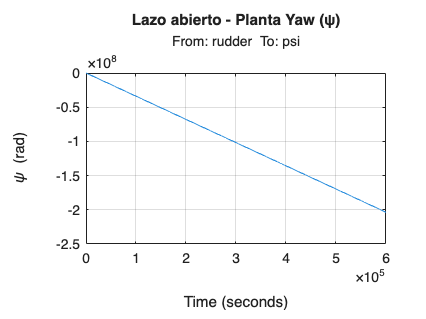


% Controlador PI
Cpi_yaw = Kp_yaw + Ki_yaw/s;

%% --- 4. Lazo cerrado total (PI + D) ---
T_yaw = feedback(Cpi_yaw * G_psi, 1);

%% --- 5. Comparación de respuestas ---
figure('Color', 'w');

figure
step(G_psi);
title('Lazo abierto - Planta Yaw (ψ)');
ylabel('\psi (rad)');
grid on;

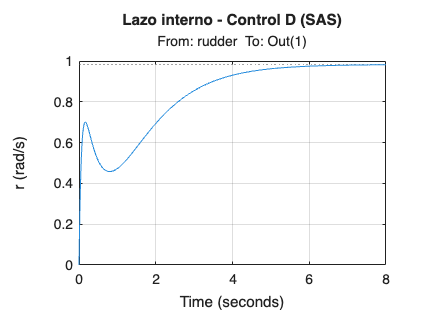


figure
step(G_sas_yaw);
title('Lazo interno - Control D (SAS)');
ylabel('r (rad/s)');
grid on;

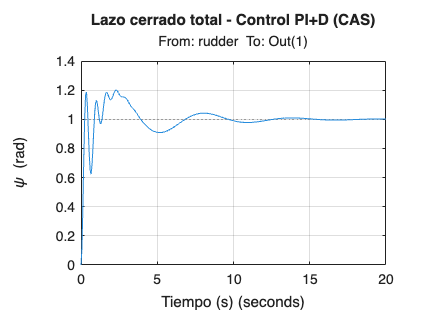


figure
step(T_yaw);
title('Lazo cerrado total - Control PI+D (CAS)');
ylabel('\psi (rad)');
xlabel('Tiempo (s)');
grid on;


infoY = stepinfo(T_yaw);
fprintf('\n[YAW] Ts = %.2f s | Overshoot = %.2f %%\n', ...
    infoY.SettlingTime, infoY.Overshoot);


[YAW] Ts = 11.34 s | Overshoot = 20.00 %
